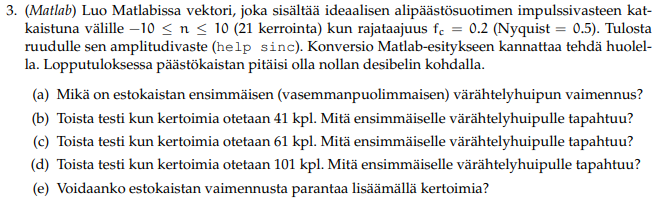

N=21

N = 21

n=-(N-1)/2:(N-1)/2;
fc=0.2*2  %pitää kertaa kahdella

fc = 0.4000

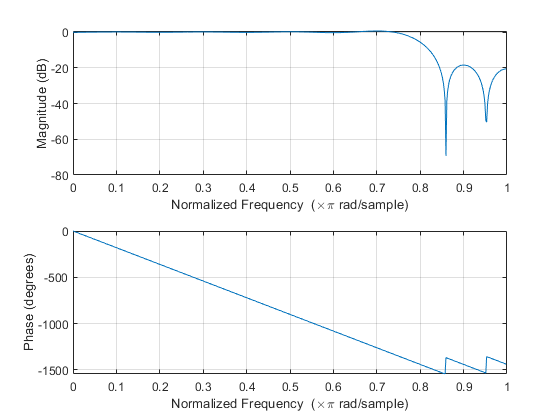

%alipäästö
%n=0
h=2*fc*sinc(n*2*fc);
freqz(h,1)

%(a) noin -20dB
N=41

N = 41

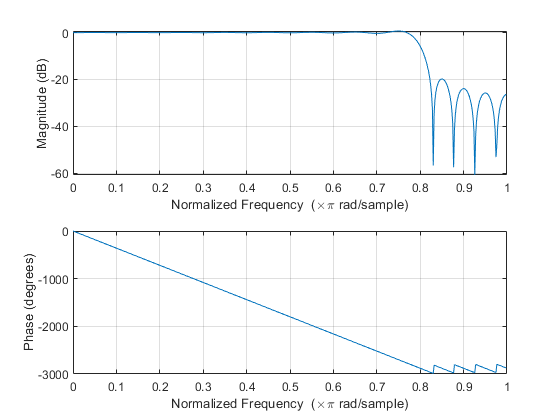

n=-(N-1)/2:(N-1)/2;
h=2*fc*sinc(n*2*fc);
freqz(h,1)

%(b)  huippu ei muuttnut
N=61

N = 61

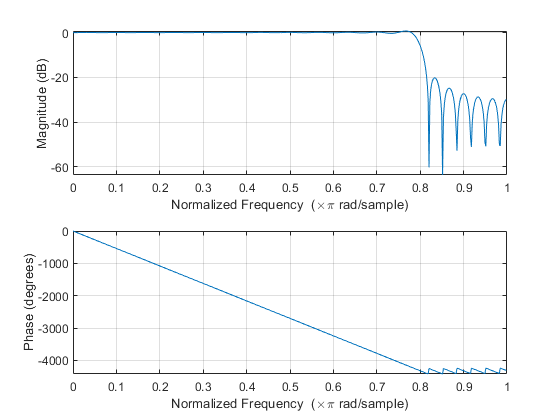

n=-(N-1)/2:(N-1)/2;
h=2*fc*sinc(n*2*fc);
freqz(h,1)

%(c)  huippu ei muuttnut
N=101

N = 101

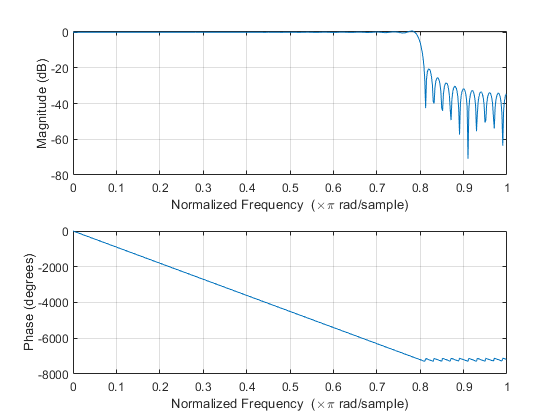

n=-(N-1)/2:(N-1)/2;
h=2*fc*sinc(n*2*fc);
freqz(h,1)

%(d)  huippu ei muuttnut
%(e) ei



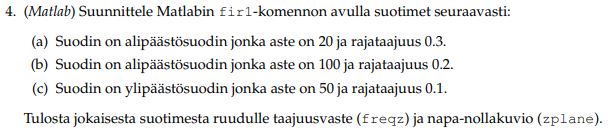

clear all
%(a)
N=21%pituus

N = 21

Wn=0.3

Wn = 0.3000

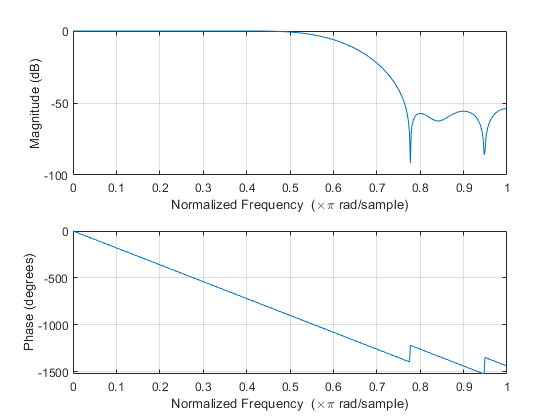

d=fir1(N-1,2*Wn,'low', hamming(N));%aste=pituus-1
freqz(d)

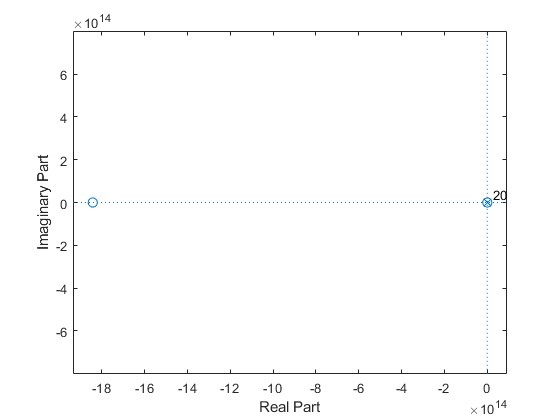

zplane(d)

%(b)
N=101

N = 101

Wn=0.2

Wn = 0.2000

b=fir1(N-1,2*Wn,'low');

b =    -0.0000   -0.0005   -0.0003    0.0004    0.0006   -0.0000   -0.0008   -0.0005    0.0006    0.0011   -0.0000   -0.0014   -0.0010    0.0011    0.0021   -0.0000   -0.0026   -0.0018    0.0020    0.0036   -0.0000   -0.0044   -0.0030    0.0033    0.0060   -0.0000   -0.0072   -0.0049    0.0053    0.0094   -0.0000   -0.0113   -0.0077    0.0084    0.0149   -0.0000   -0.0180   -0.0123    0.0137    0.0246   -0.0000   -0.0312   -0.0221    0.0256    0.0489   -0.0000   -0.0746   -0.0619    0.0933    0.3027


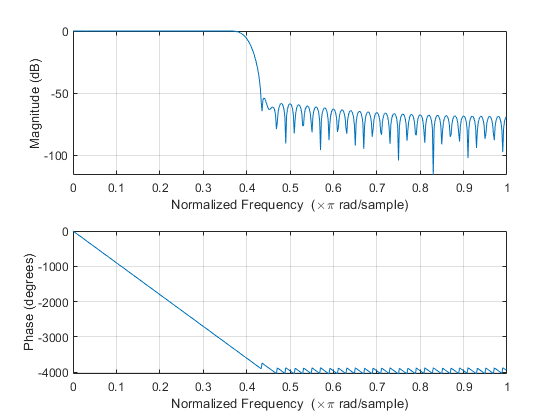

freqz(b)

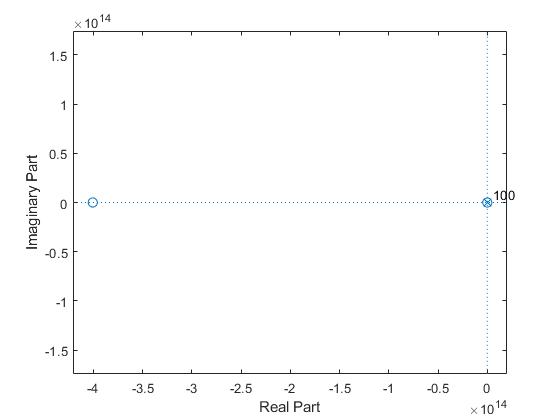

figure,zplane(b)

%(c)
N=51

N = 51

Wn=0.1

Wn = 0.1000

h=fir1(N-1,2*Wn,'high')

h =    -0.0000   -0.0007   -0.0012   -0.0015   -0.0012   -0.0000    0.0020    0.0042    0.0052    0.0040    0.0000   -0.0061   -0.0119   -0.0144   -0.0107   -0.0000    0.0153    0.0298    0.0360    0.0273    0.0000   -0.0441   -0.0977   -0.1492   -0.1865    0.8003   -0.1865   -0.1492   -0.0977   -0.0441    0.0000    0.0273    0.0360    0.0298    0.0153   -0.0000   -0.0107   -0.0144   -0.0119   -0.0061    0.0000    0.0040    0.0052    0.0042    0.0020   -0.0000   -0.0012   -0.0015   -0.0012   -0.0007


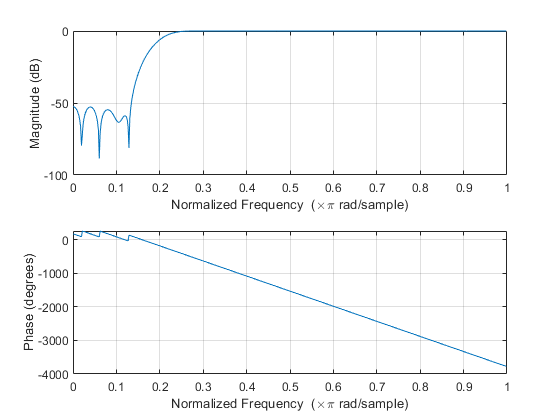

freqz(h,1)

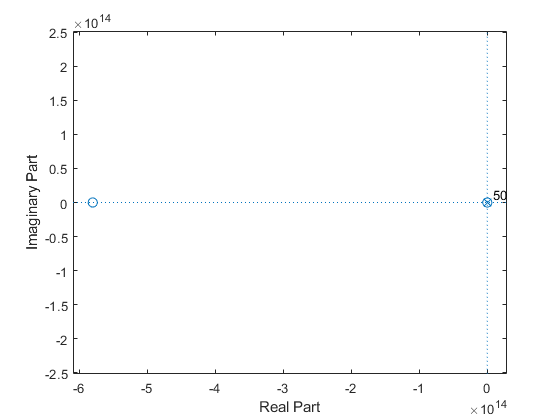

zplane(h)

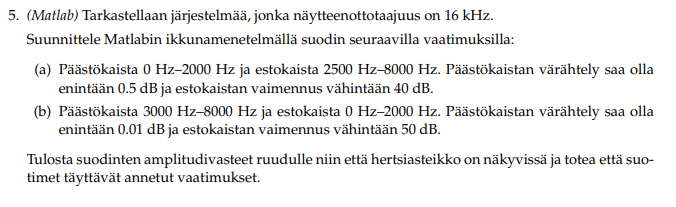

clear all
Fs=16000

Fs = 16000

%(a)Hanning alipaasto
fc=(2500+2000)/2/Fs

fc = 0.1406

N=3.1/((2500-2000)/(Fs))

N = 99.2000

N=101

N = 101

n=-(N-1)/2:(N-1)/2

n =    -50   -49   -48   -47   -46   -45   -44   -43   -42   -41   -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1


h=2*fc*sinc(n*2*fc)

h =     0.0012   -0.0041   -0.0066   -0.0043    0.0013    0.0062    0.0067    0.0021   -0.0042   -0.0077   -0.0056    0.0008    0.0070    0.0082    0.0034   -0.0043   -0.0092   -0.0075    0.0000    0.0079    0.0104    0.0052   -0.0044   -0.0113   -0.0102   -0.0012    0.0094    0.0138    0.0080   -0.0044   -0.0147   -0.0148   -0.0034    0.0119    0.0199    0.0135   -0.0044   -0.0216   -0.0245   -0.0084    0.0177    0.0352    0.0281   -0.0045   -0.0441   -0.0609   -0.0305    0.0500    0.1561    0.2461


h((N-1)/2+1)=2*fc

h =     0.0012   -0.0041   -0.0066   -0.0043    0.0013    0.0062    0.0067    0.0021   -0.0042   -0.0077   -0.0056    0.0008    0.0070    0.0082    0.0034   -0.0043   -0.0092   -0.0075    0.0000    0.0079    0.0104    0.0052   -0.0044   -0.0113   -0.0102   -0.0012    0.0094    0.0138    0.0080   -0.0044   -0.0147   -0.0148   -0.0034    0.0119    0.0199    0.0135   -0.0044   -0.0216   -0.0245   -0.0084    0.0177    0.0352    0.0281   -0.0045   -0.0441   -0.0609   -0.0305    0.0500    0.1561    0.2461


w=hanning(N)

w =     0.0009
    0.0038
    0.0085
    0.0151
    0.0235
    0.0338
    0.0458
    0.0595
    0.0749
    0.0919


ht=w.*h'

ht =     0.0000
   -0.0000
   -0.0001
   -0.0001
    0.0000
    0.0002
    0.0003
    0.0001
   -0.0003
   -0.0007


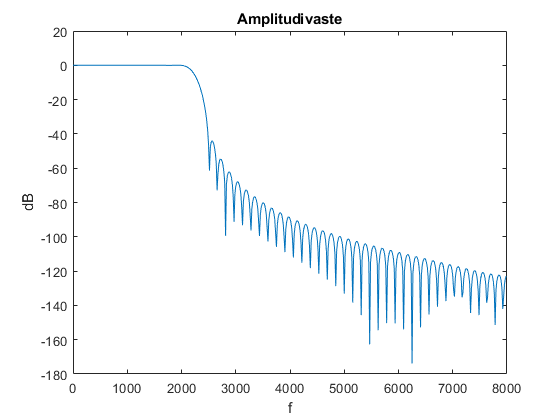

[H,w]=freqz(ht);
plot(Fs*w/(2*pi),20*log10(abs(H)))%Fs*w/(2*pi)=f
title('Amplitudivaste')
xlabel('f') 
ylabel('dB')

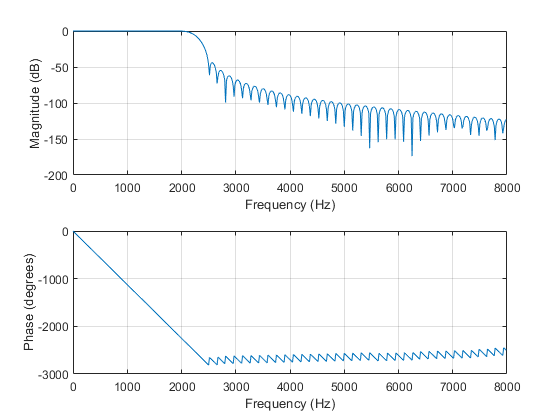

%tapa2=====================================================
w=hanning(N);% parametrina on kuitenkin termien pituus w koko on 101
h_a = fir1(N-1,2*fc, 'low',w); %Aste=pituus-1. Ulostulon koko on kuitenkin N-1+1
freqz(h_a,1,[],Fs);


%(b)Blackman ylipaasto
fc=(3000+2000)/2/16000

fc = 0.1563

N=5.5/((3000-2000)/(16000))

N = 88

N=89

N = 89

n=-(N-1)/2:(N-1)/2

n =    -44   -43   -42   -41   -40   -39   -38   -37   -36   -35   -34   -33   -32   -31   -30   -29   -28   -27   -26   -25   -24   -23   -22   -21   -20   -19   -18   -17   -16   -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5


h=-2*fc*sinc(n*2*fc)

h =     0.0051    0.0073    0.0029   -0.0043   -0.0080   -0.0045    0.0032    0.0084    0.0063   -0.0018   -0.0086   -0.0080    0.0000    0.0085    0.0098    0.0021   -0.0080   -0.0116   -0.0047    0.0071    0.0133    0.0077   -0.0055   -0.0149   -0.0113    0.0033    0.0163    0.0156   -0.0000   -0.0176   -0.0210   -0.0048    0.0188    0.0284    0.0122   -0.0196   -0.0398   -0.0253    0.0203    0.0624    0.0563   -0.0207   -0.1470   -0.2647   -0.3125   -0.2647   -0.1470   -0.0207    0.0563    0.0624


h((N-1)/2+1)=1-2*fc

h =     0.0051    0.0073    0.0029   -0.0043   -0.0080   -0.0045    0.0032    0.0084    0.0063   -0.0018   -0.0086   -0.0080    0.0000    0.0085    0.0098    0.0021   -0.0080   -0.0116   -0.0047    0.0071    0.0133    0.0077   -0.0055   -0.0149   -0.0113    0.0033    0.0163    0.0156   -0.0000   -0.0176   -0.0210   -0.0048    0.0188    0.0284    0.0122   -0.0196   -0.0398   -0.0253    0.0203    0.0624    0.0563   -0.0207   -0.1470   -0.2647    0.6875   -0.2647   -0.1470   -0.0207    0.0563    0.0624


w=blackman(N)

w =          0
    0.0005
    0.0018
    0.0042
    0.0076
    0.0120
    0.0176
    0.0244
    0.0326
    0.0423


ht=w.*h'

ht =          0
    0.0000
    0.0000
   -0.0000
   -0.0001
   -0.0001
    0.0001
    0.0002
    0.0002
   -0.0001


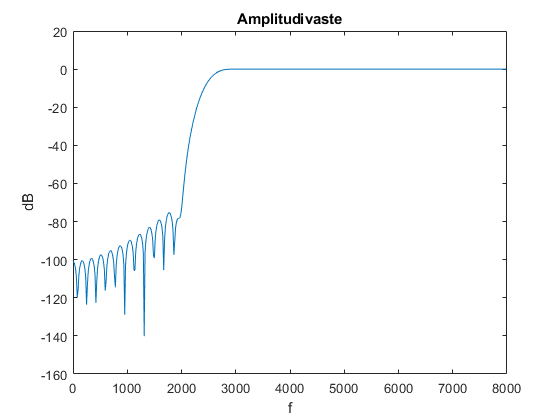

[H,w]=freqz(ht);
plot(Fs*w/(2*pi),20*log10(abs(H)))%Fs*w/(2*pi=f
title('Amplitudivaste')
xlabel('f') 
ylabel('dB')